% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty     uom 
    _________    _____    ___________    _____

     {'s1'}      1.775       0.001       {'m'}
     {'s2'}      1.105       0.001       {'m'}
     {'s3'}      0.425       0.001       {'m'}
     {'su'}      0.539       0.001       {'m'}
     {'m0'}       9.85        0.01       {'g'}
     {'m1'}      10.23        0.01       {'g'}
     {'m2'}       20.1        0.01       {'g'}
     {'m3'}      30.33        0.01       {'g'}
     {'m4'}      40.21        0.01       {'g'}
     {'M' }      296.5         0.1       {'g'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 50×6 table
    index      mass        t1       t2      uncertainty     uom 
    _____    _________    _____    _____    ___________    _____

      1      {'m0'   }    2.704    1.291       0.001       {'s'}
      2      {'m0'   }    2.674    1.264       0.001       {'s'}
      3      {'m0'   }    2.372     1.12       0.001       {'s'}
      4      {'m0'   }    2.587     1.22       0.001       {'s'}
      5      {'m0'   }    2.532    1.193       0.001       {'s'}
      6      {'m0'   }    2.655    1.256       0.001       {'s'}
      7      {'m0'   }    2.518    1.197       0.001       {'s'}
      8      {'m0'   }    2.663    1.259       0.001       {'s'}
      9      {'m0'   }    2.713    1.292       0.001       {'s'}
     10      {'m0'   }    2.801    1.334       0.001       {'s'

tools=readtable("..\data\tools.csv")

tools = 3×3 table
         tool         uncertainty     uom 
    ______________    ___________    _____

    {'Bilancia'  }        0.01       {'g'}
    {'Metro'     }       0.001       {'m'}
    {'Cronometro'}       0.001       {'s'}


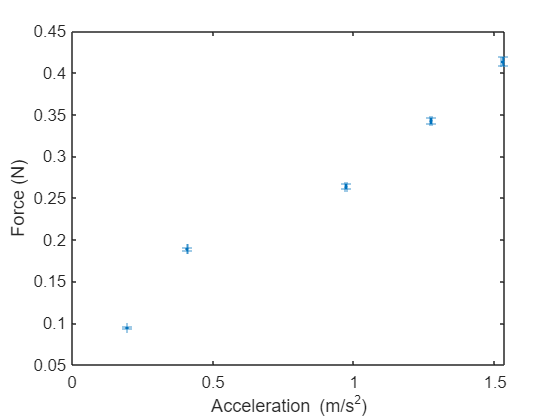

% defining variables
t0=df2.t1(1:10,:);
t1=df2.t1(11:20,:);
t2=df2.t1(21:30,:);
t3=df2.t1(31:40,:);
t4=df2.t1(41:50,:);
s1=df1.value(1);
s2=df1.value(2);
ds=df1.uncertainty(1);
dm=df1.uncertainty(5)./1000; %kg
dt=df2.uncertainty(2);

% average t
tm0=mean(t0);
tm1=mean(t1);
tm2=mean(t2);
tm3=mean(t3);
tm4=mean(t4);

% creating array for t
tm=[tm0,tm1,tm2,tm3,tm4];
lt=length(tm);

% space
s=s1-s2;

% gravitational acceleration
g=9.8;
dg=0.1;

% masses in g
m=zeros(lt,1);
m(1)=df1.value(5);
m(2)=m(1)+df1.value(6);
m(3)=m(1)+df1.value(7);
m(4)=m(1)+df1.value(8);
m(5)=m(1)+df1.value(9);

% masses in kg
m=m/1000;

% creating empty array
a=zeros(lt,1);      % acceleration
da=zeros(lt,1);     % delta a
rea=zeros(lt,1);    % relative error a
cfra=zeros(lt,1);   % position first significant digit da
cfrf=zeros(lt,1);   % position first significant digit df
f=zeros(lt,1);      % force
df=zeros(lt,1);     % delta F
ref=zeros(lt,1);     % relative error force

% core
for i=1:lt

    % acceleration
    a(i)=(2.*s)./(tm(i))^2;

    % force
    f(i)=m(i).*(g-a(i));
    
    % propagation of error acceleration
    da(i)=(2.*ds+((4.*s.*dt)/(tm(i))))./(tm(i).^2);
    cfra(i)=-floor(log10(da(i)));   % position first significant digit a
    da(i)=round(da(i),cfra(i));     % round da
    a(i)=round(a(i),cfra(i));       %round acceleration
    
    % propagation of error force
    df(i)=((g-a(i))*2*dm)+(m(i)*dg)+(m(i)*((2.*ds+((4.*s.*dt)/(tm(i))))./(tm(i).^2)));
    cfrf(i)=-floor(log10(df(i)));   % position first significant digit f
    df(i)=round(df(i),cfrf(i));     % round df
    f(i)=round(f(i),cfrf(i));       % round f
    
    % relative error
    rea(i)=round((da(i)./a(i))*100,2);  % relative error a
    ref(i)=round((df(i)./f(i))*100,2);  % relative error f
end

% plotting
scatter=figure;
errorbar(a,f,df,df,da,da,'.')
xlabel('Acceleration (m/s^2)')
ylabel('Force (N)')


% visualize force array
force=horzcat(f,df,ref)

force =     0.0950    0.0010    1.0500
    0.1890    0.0020    1.0600
    0.2640    0.0030    1.1400
    0.3430    0.0040    1.1700
    0.4140    0.0050    1.2100



% visualize acceleration array
acceleration=horzcat(a,da,rea)

acceleration =     0.1949    0.0004    0.2100
    0.4110    0.0010    0.2400
    0.9740    0.0030    0.3100
    1.2750    0.0040    0.3100
    1.5300    0.0060    0.3900



% significant digits
as=zeros(lt,1);     % acceleration significant digits
fs=zeros(lt,1);     % force significant digits

for i=1:lt
    as(i)=sprintf(strcat('%.',string(cfra(i)),'f'),a(i));
    fs(i)=sprintf(strcat('%.',string(cfrf(i)),'f'),f(i));
end

% converting array to string
a=string(a);
da=string(da);
rea=string(rea);
f=string(f);
df=string(df);
ref=string(ref);

% creating uom array
uoma=string(zeros(lt,1));
uomf=string(zeros(lt,1));

% substituting values
for i=1:lt
    a(i)=as(i);
    f(i)=fs(i);
    rea(i)=sprintf('%.2f',rea(i));
    ref(i)=sprintf('%.2f',ref(i));
    uoma(i)='MSK';
    uomf(i)='NEW';
end

% creating output array
acceleration=horzcat(a,da,uoma,rea)

acceleration = 5×4 string array
    "0.1949"    "0.0004"    "MSK"    "0.21"
    "0.411"     "0.001"     "MSK"    "0.24"
    "0.974"     "0.003"     "MSK"    "0.31"
    "1.275"     "0.004"     "MSK"    "0.31"
    "1.53"      "0.006"     "MSK"    "0.39"


force=horzcat(f,df,uomf,ref)

force = 5×4 string array
    "0.095"    "0.001"    "NEW"    "1.05"
    "0.189"    "0.002"    "NEW"    "1.06"
    "0.264"    "0.003"    "NEW"    "1.14"
    "0.343"    "0.004"    "NEW"    "1.17"
    "0.414"    "0.005"    "NEW"    "1.21"



% testing (deleted m2)
% a2=zeros(lt-1,1);
% f2=zeros(lt-1,1);
% a2(1)=a(1);
% a2(2)=a(3);
% a2(3)=a(4);
% a2(4)=a(5);
% 
% f2(1)=f(1);
% f2(2)=f(3);
% f2(3)=f(4);
% f2(4)=f(5);

% exporting csv
writetable(array2table(acceleration,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(array2table(force,'VariableNames',{'force','uncertainty','uom','relative_error'}),'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(scatter,'..\img\img-1.png');

%saveas(name-figure,'..\img\img-2.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);